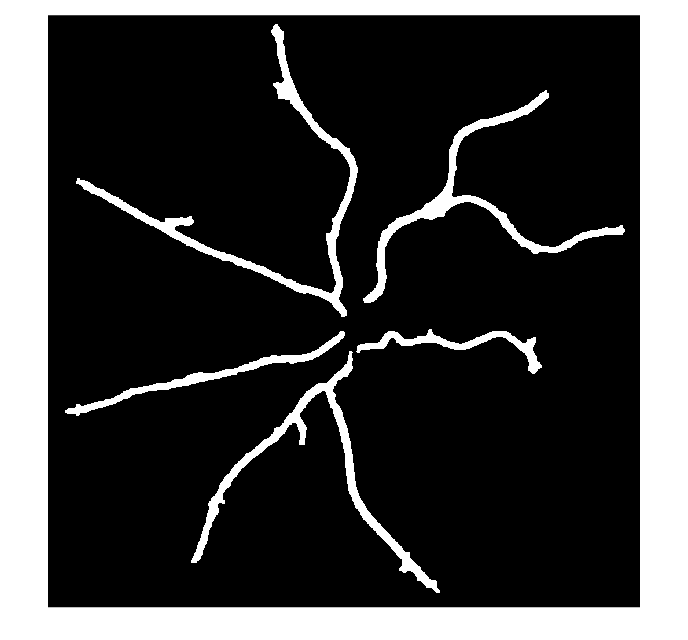

I = imread("X:\240715_FIY0713\240715_FIY0713_ODD_HD_1\pulsewave\240715_FIY0713_ODD_HD_1_PW_6\png\mask\240715_FIY0713_ODD_HD_1_maskArtery_New.png");
I = logical (I);
[nX, nY] = size(I);
imshow (I)

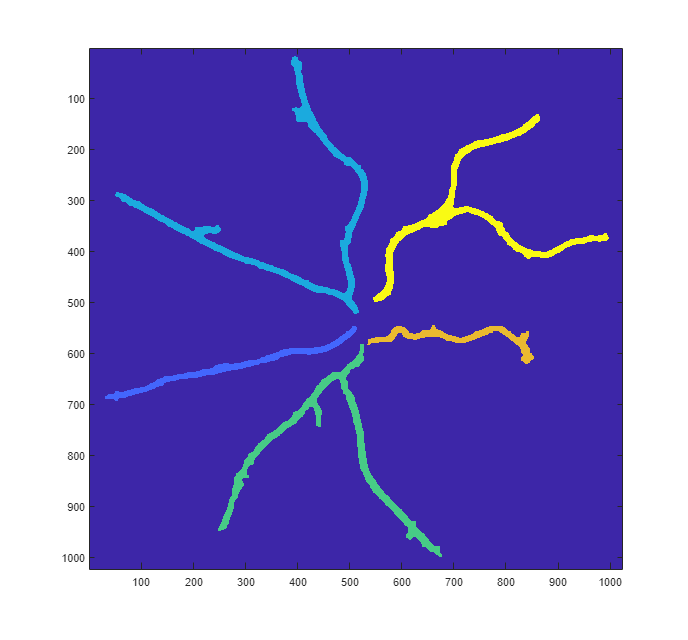

labels = bwlabel(I);
imagesc(labels)

% I = imclose(I, strel("disk",15));
% imagesc(I)

skel= imskel(I);

Unrecognized function or variable 'imskel'.

B = bwmorph(skel, 'branchpoints');
E = bwmorph(skel, 'endpoints');
[y,x] = find(E);
B_loc = find(B);
Dmask = false(size(skel));
for k = 1:numel(x)
    D = bwdistgeodesic(skel,x(k),y(k));
    distanceToBranchPt = min(D(B_loc));
    Dmask(D < distanceToBranchPt) =true;
end
skelD = skel - Dmask;
imshow(skelD);
hold all;
[y,x] = find(B); plot(x,y,'ro')

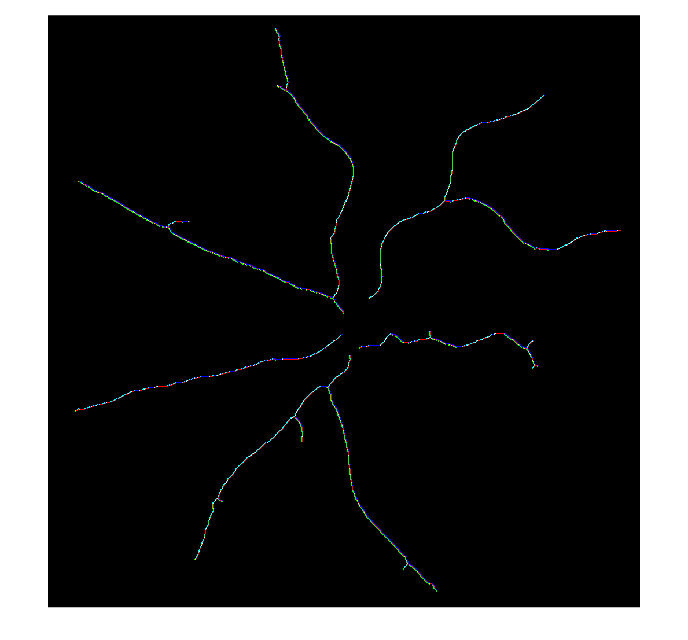

[Gx, Gy] = imgradientxy(skeleton);
Image = zeros(nX, nY, 'double');
Image(:,:,1) = double(skeleton) * 8 ; %ROUGE
Image(:,:,2) = Gx;
Image(:,:,3) = Gy;
imshow(Image)

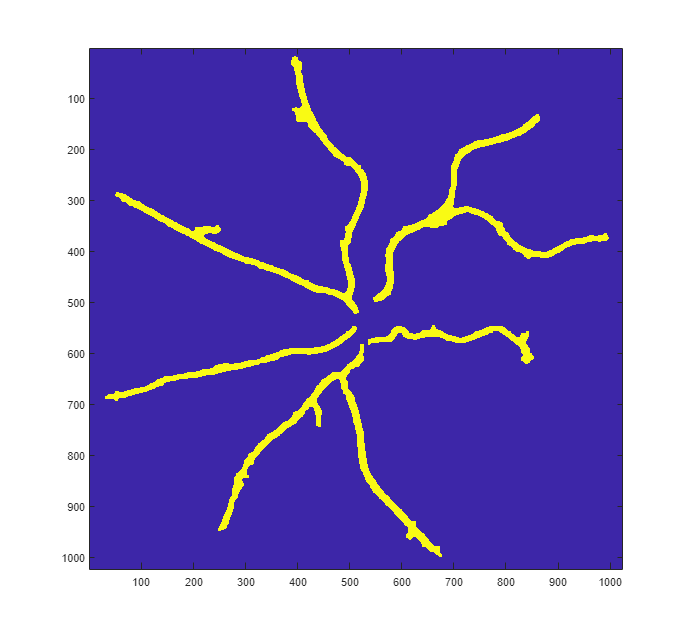

% branchpoints = bwmorph(skeleton, 'branchpoints');
% SE = strel("disk",25);
% branchcircles = imdilate(branchpoints, SE);
% imagesc(branchcircles)

% filteredMask = I & (~branchcircles);
filteredMask = bwmorph(I, "spur");
imagesc(filteredMask)

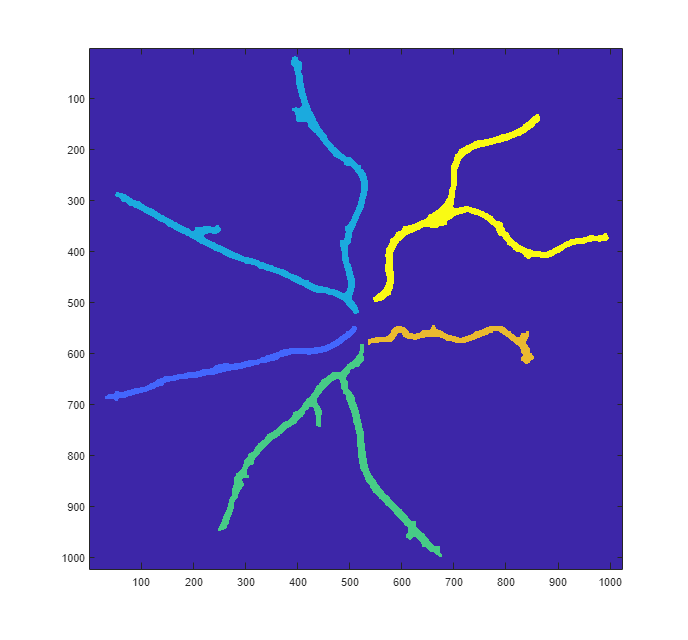

labels = bwlabel(filteredMask);
imagesc(labels)